# MATLAB Production Server and fastAPI: Communicate between MATLAB & Python microservices

## Python function

The main.py Python file contains the simple *customProcessing* function.

type main.py

from fastapi import FastAPI
from fastapi import Request

app = FastAPI()

@app.post("/customProcessing/")
def customProcessing(a: float, thd: float, request: Request):
    if a > thd:
        y = 1
    else:
        y = 0
    client_host = request.client.host
    return {"client_host": client_host, "y": y}


## Run fastAPI server

type deployFastAPI.mlx

!pip install uvicorn
!uvicorn main:app --reload


## Test local MATLAB function

The MATLAB function calls simply the Python function.

% none reproducible error
try %#ok<*TRYNC> 
myMATLABFunction(2,1)
end

ans = 1

try
    myMATLABFunction(1,2)
end
try
myMATLABFunction(1,2)
end

ans = 0

## MPS dashboard

### Run MPS dashboard

### Add myMATLABFunction ctf file to the MPS instance

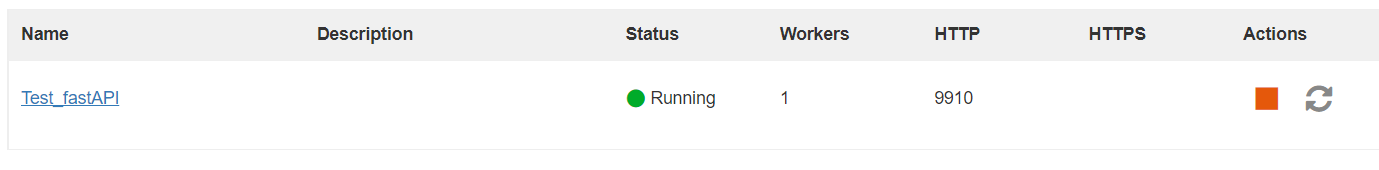

### Test MATLAB function (calling Python) with Postman request

To make request, we use [Postman](https://www.postman.com/) API platform here.